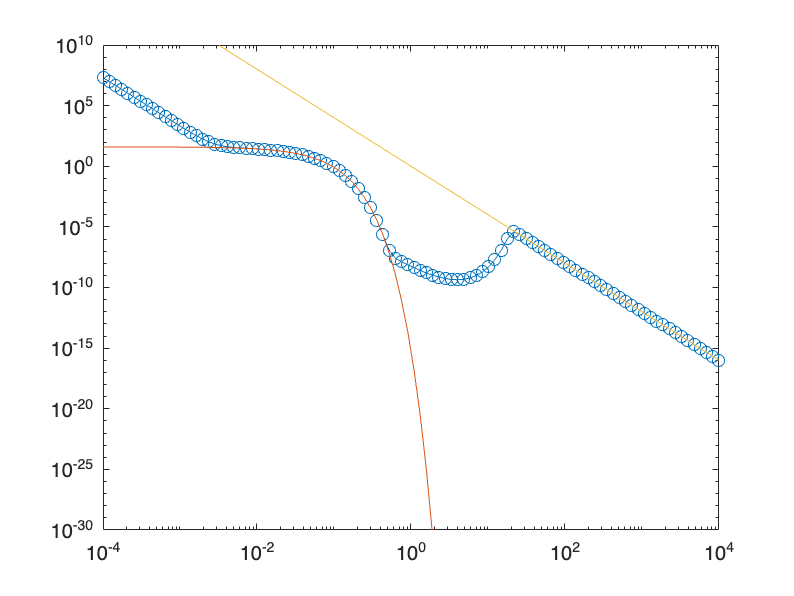

x_min = 1e-4;
x_max = 1e4;
transmission_n = 100;

x = logspace(log10(x_min), log10(x_max), transmission_n);


c = 3*10^(10);
m = 9.1*10^(-28);
h = 6.63*10^(-27);
E = 4.8*10^(-10);
k = 1.38*10^(-16);
H = 4.14*10^(-15);
Z = 1;
s = 5;
v = 10^6;
n = 10^(20);
T = 5;
TA = 300;
TB = 3000;

p = 1;%1e-4;
l = 300;%0.003;

% I_assumption = zeros(size(x));
% I_assumption(x* p <= l) = (2^5 * pi * E^6 / (3 * c^3 * m)) * sqrt(2 * pi / (3 * m * k)) * ...
%      n^2 * Z^2 * T^(-0.5) .* exp(-h *p*x(x* p<=l) ./ (H * k * T));

I_assumptionA = (2^5 * pi * E^6 / (3 * c^3 * m)) * sqrt(2 * pi / (3 * m * k)) * ...
     n^2 * Z^2 * TA^(-0.5) .* exp(-h*x ./ (H * k * TA));

% % Calculate I_assumption2 where x > 0
% I_assumptionB = (16 * pi * E^6 / (sqrt(3) * c^3 * m^2)) * n^2 * Z^2 * (2 * s - 3) / (2 * s - 2) * ...
%     v^(2 * s - 3) ./ (2 * h * 1e-6 * x / (H * m)).^(s - 1);
I_assumptionB = (2^5 * pi * E^6 / (3 * c^3 * m)) * sqrt(2 * pi / (3 * m * k)) * ...
     n^2 * Z^2 * TB^(-0.5) .* exp(-h *x ./ (H * k * TB));
I_assumptionB = x.^(1-s);
% % Calculate I_assumption2 where x > 0
% I_assumption(x* p > l) = (16 * pi * E^6 / (sqrt(3) * c^3 * m^2)) * n^2 * Z^2 * (2 * s - 3) / (2 * s - 2) * ...
%     v^(2 * s - 3) ./ (2 * h * p * x( x* p > l) / (H * m)).^(s - 1);

threshold = 20;
I_assumption = I_assumptionA.*(1+exp((1*(x-threshold)))).^(-1)+ I_assumptionB.*(1+exp(-(1*(x-threshold)))).^(-1);

figure;

loglog(x,I_assumption, 'o-');
hold on;
loglog(x,I_assumptionA);
hold on;
loglog(x,I_assumptionB);
hold off;
xlim([x_min x_max]);
ylim([1e-30 1e10])